# SumCa_new

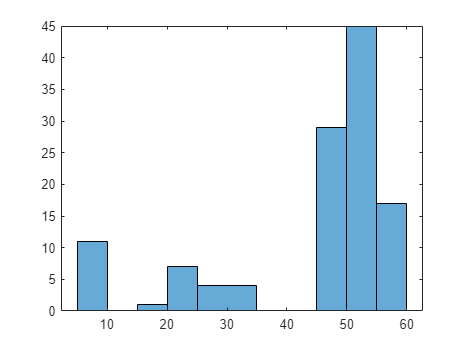

clear
close all
path = uigetdir('E:\Dropbox (HMS)\LQCalciumImaging1\analysis\');
temp = strsplit(path,filesep);
cell_type = temp{end};
sumStructName = fullfile(path, [cell_type, '.mat']);
sumStruct = struct;

d = dir(path);
d = d(~ismember({d.name},{'.','..'}));
d = d([d(:).isdir]);

index = [];
for i = 1:numel(d)
    temp = [path, filesep, d(i).name,filesep,'sum.mat'];
    if isfile(temp)
        index = [index; i];  
    end
end

sumStruct.dataToPlot = [];
sumStruct.responder = {};
sumStruct.mouseID = {};
sumStruct.poly = {};

for i = 1:numel(index)
    load([path, filesep, d(index(i)).name,filesep,'sum.mat'])
    sumStruct.dataToPlot = [sumStruct.dataToPlot, sum.dataToPlot];
    for j = 1:numel(sum.responder)
        sumStruct.responder = [sumStruct.responder; [sum.mouseID,'_cell_',num2str(sum.responder(j))]];
    end
    sumStruct.mouseID = [sumStruct.mouseID; sum.mouseID];
    T1 = readtable([path,filesep, d(index(i)).name,filesep, 'responseSum_.xlsx']);
    sumStruct.poly = [sumStruct.poly; T1.poly]; 
end
clear sum
dataToPlot = sumStruct.dataToPlot;

thermal_threshold = [];
inhibition = [];
delta = [];
for i = 1:numel(index)
    T1 = readtable(fullfile(path, d(index(i)).name, 'responseSum_.xlsx'));
    inhibition = [inhibition; T1.i]; %#ok<*AGROW> 
    delta = [delta; T1.delta];  
    thermal_threshold = [thermal_threshold; T1.heat_threshold;T1.cool_threshold];  
end
thermal_threshold = thermal_threshold(~isnan(thermal_threshold));
edges = [5:5:25 35:5:60]; % temperature stimuli
h = histogram(thermal_threshold, edges);

percent = h.Values/size(dataToPlot,2);

inhibition(isnan(inhibition)) = 0;
delta(isnan(delta)) = 0;
delta(inhibition == 1) = 0; % is the cell can be inhibited, set the delta as 0;
sumStruct.thermal_threshold = thermal_threshold;
sumStruct.percent = percent;
sumStruct.inhibition = inhibition;
sumStruct.delta = delta;
save(sumStructName,'sumStruct');

#### Plot all responses in heatmap

f1 = mhc(resetbase(dataToPlot));

Unrecognized function or variable 'dataToPlot'.

saveas(f1, [path,filesep,'allSum_',cell_type,'.png']);

#### Plot the delta activity

delta_dataToPlot = dataToPlot(1:6000, delta ==1);
f2 = thermaltrace(delta_dataToPlot);
saveas(f2, [path,filesep,'delta.png']);

#### Plot the non-delta activity (in contrast to delta activity)

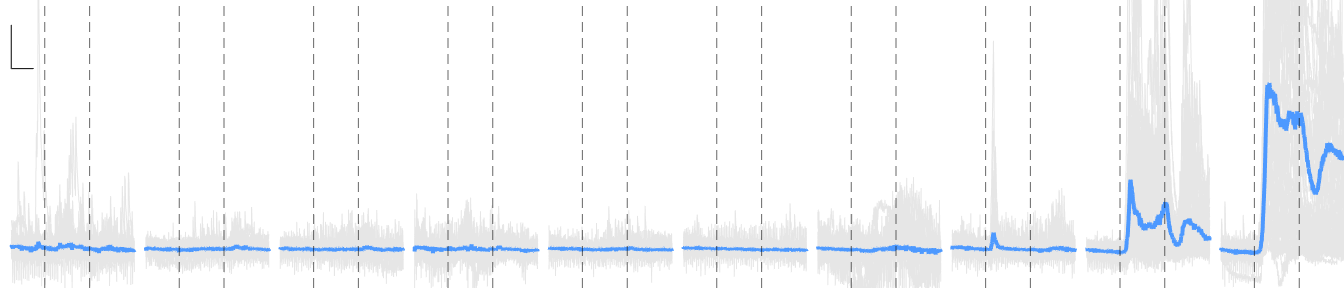

indexHC = [];
for i = 1:size(dataToPlot,2)
    % if contains(sumStruct.poly{i}, 'H') || contains (sumStruct.poly{i}, 'C')
    if contains(sumStruct.poly{i}, 'H') && inhibition(i)==0
        indexHC = [indexHC; i];
    end
end
index_nondelta = intersect(find(delta ==0),indexHC);
% f2 = thermaltrace(resetbase(nondelta_dataToPlot));
f2 = thermaltrace(dataToPlot(1:6000, index_nondelta));
saveas(f2, [path,filesep,'non_delta.png']);

#### Plot the inhibtion activity

i_dataToPlot = dataToPlot(1:6000, inhibition == 1);
f3 = thermaltrace(resetbase(i_dataToPlot));
saveas(f3, [path,filesep,'inhibition.png']);

#### Plot all responses in traces (no shade,all traces)

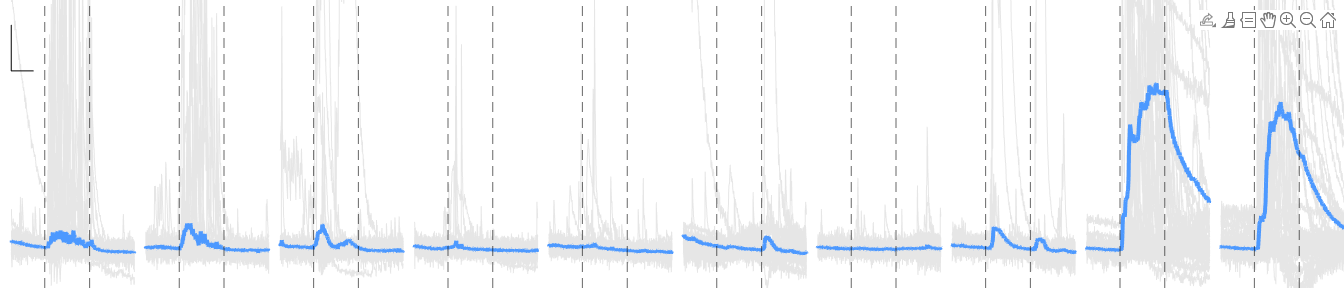

indexHC = [];
for i = 1:size(dataToPlot,2)
    if contains(sumStruct.poly{i}, 'H') || contains (sumStruct.poly{i}, 'C')
        indexHC = [indexHC; i];
    end
end
f4 = thermaltrace(dataToPlot(1:6000,indexHC));
saveas(f4, [path,filesep,cell_type,'_trace.png']);

#### Plot all responses in heatmap (from mechanical to temperature) of all cell types

clear
close all
% path = uigetdir('D:\dropbox\Dropbox (HMS)\LQCalciumImaging1\');
% path = uigetdir('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging1\analysis\');
path = uigetdir('E:\Dropbox (HMS)\LQCalciumImaging1\analysis\');
di = dir(path);
di = di(~ismember({di.name},{'.','..'}));
di = di([di(:).isdir]);
index = [];
for i = 1:numel(di)
    cell_type = di(i).name;
    temp = [path, filesep, di(i).name,filesep,[cell_type,'.mat']];
    if isfile(temp)
        index = [index; i];
    end
end
for k = 1:numel(index)
% for k = 1
    load([path, filesep, di(index(k)).name,filesep,[di(index(k)).name,'.mat']]);
%    f = mhc(sumStruct.dataToPlot);
%    f = mhcnoe(sumStruct.dataToPlot);
    f = mhcsep(sumStruct.dataToPlot);
    % exportgraphics(f,[path,filesep,'allSum_new_',di(index(k)).name,'.png'],"Resolution",300);
    saveas(f, [path,filesep,'allSum_new_',di(index(k)).name,'.png']);
    close all
end


Special: Plot the heat responsive cell for Trpm8 neurons

poly = sumStruct.poly;
indexH = [];
for i = 1:size(dataToPlot,2)
    if contains(poly{i}, 'H')
        indexH = [indexH; i];
    end
end

h_dataToPlot = dataToPlot(1:6000,indexH);
f5 = thermaltrace(h_dataToPlot);
saveas(f5, [path,filesep,'heat.png']);

Special: Plot the heat and dynamic responsive cell for Trpm8 neurons

poly = sumStruct.poly;
indexH = [];
for i = 1:size(dataToPlot,2)
    if contains(poly{i}, 'H')
        indexH = [indexH; i];
    end
end
indexHD = unique([indexH; find(delta)]);

hd_dataToPlot = dataToPlot(1:6000,indexHD);
f5 = thermaltrace(resetbase(hd_dataToPlot));
saveas(f5, [path,filesep,'heat_delta.png']);

Special: Plot the Plain (non-inhibited or heat) responsive cell for Trpm8 neurons

poly = sumStruct.poly;
indexP = [];
for i = 1:size(dataToPlot,2)
    if ~contains(poly{i}, 'H') && contains(poly{i}, 'C') && ~delta(i) && ~inhibition(i)
        indexP = [indexP; i];
    end
end

p_dataToPlot = dataToPlot(1:6000,indexP);
f5 = thermaltrace(resetbase(p_dataToPlot));
saveas(f5, [path,filesep,'plain.png']);

Special: correct the drafted baseline of MrgA3 at 5C due to blood covering

dataToPlot (401:600,:) = randn(200,size(dataToPlot,2)) * 0.02;

Special: clean up the base line for Trpm8 (make baseline to zero)

sessionBreak = zeros(size(dataToPlot));
startPoint = 1:600: 6001;
for i= 1:numel(startPoint)-1
    baseline = mean(dataToPlot(startPoint(i):startPoint(i)+149,:));
    sessionBreak(startPoint(i):startPoint(i+1)-1,:) = dataToPlot(startPoint(i):startPoint(i+1)-1,:)-baseline;
end
sessionBreak(startPoint(end):9400,:) = dataToPlot(startPoint(end):9400,:);
dataToPlot = sessionBreak;

function f = mhc(dataToPlot)
f = figure('units','inch',"Position", [1, 1, 14, 2]);
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
ax = gca;
outerpos = ax.OuterPosition;
left = outerpos(1);
ti = ax.TightInset;
% bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(3) - ti(1);
% ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left outerpos(2) ax_width outerpos(4)];
[~, ia] = sort(sum(dataToPlot), 'descend');
A = [dataToPlot(:,ia); zeros(100, numel(ia))];
B = zeros(size(A));
B(1:2800,:) = A(6001:8800,:);
B(2801:8800,:) = A(1:6000,:);
B(8801:end,:) = A(8801:end,:);
B(end-100:end,:) = nan;                                                                                                                                                                                                                                                                                                                                                                   
imagesc(B', 'AlphaData', ~isnan(B'));
colormap('turbo')
caxis([0.05, 1])
box off
% axis off
ax.YAxis.Visible = 'off';
ax.XAxis.Visible = 'off';
hold on
for i = 1:10
    p1 = line([600*(i-1)+200+2800, 600*(i-1)+200+2800], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p2 = line([600*(i-1)+400+2800, 600*(i-1)+400+2800], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p1.Color(4) = 0.4;
    p2.Color(4) = 0.4;
    line([600*i+2800,600*i+2800],[0 size(dataToPlot, 2)+0.5],'color','white', 'Linewidth', 2)
end
for i = 1:7
    p1 = line([400*(i-1)+100 , 400*(i-1)+100 ], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p2 = line([400*(i-1)+300, 400*(i-1)+300 ], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p1.Color(4) = 0.4;
    p2.Color(4) = 0.4;
    line([400*i ,400*i ],[0 size(dataToPlot, 2)+0.5],'color','white', 'Linewidth', 2)
end

plot([9450, 9450], [ax.YLim(2)*0.98, ax.YLim(2)*0.98-10],'LineWidth',2)

end

function f = mhcnoe(dataToPlot)

f = figure('units','inch',"Position", [1, 1, 14, 1]);
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
ax = gca;
ax.Position = ax.OuterPosition;
% outerpos = ax.OuterPosition;
% left = outerpos(1);
% ti = ax.TightInset;
% bottom = outerpos(2) + ti(2);
% ax_width = outerpos(3) - ti(3) - ti(1);
% ax_height = outerpos(4) - ti(2) - ti(4);
% ax.Position = [left outerpos(2) ax_width outerpos(4)];
[~, ia] = sort(sum(dataToPlot), 'descend');
A = [dataToPlot(1:8800,ia); zeros(100, numel(ia))];
B = zeros(size(A));
B(1:2800,:) = A(6001:8800,:);
B(2801:8800,:) = A(1:6000,:);
B(end-100:end,:) = nan;                                                                                                                                                                                                                                                                                                                                                                   
imagesc(B', 'AlphaData', ~isnan(B'));
colormap('turbo')
caxis([0.05, 1])
box off
% axis off
ax.YAxis.Visible = 'off';
ax.XAxis.Visible = 'off';
hold on
for i = 1:10
    p1 = line([600*(i-1)+200+2800, 600*(i-1)+200+2800], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p2 = line([600*(i-1)+400+2800, 600*(i-1)+400+2800], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p1.Color(4) = 0.4;
    p2.Color(4) = 0.4;
    line([600*i+2800,600*i+2800],[0 size(dataToPlot, 2)+0.5],'color','white', 'Linewidth', 2)
end
for i = 1:7
    p1 = line([400*(i-1)+100 , 400*(i-1)+100 ], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p2 = line([400*(i-1)+300, 400*(i-1)+300 ], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p1.Color(4) = 0.4;
    p2.Color(4) = 0.4;
    line([400*i ,400*i ],[0 size(dataToPlot, 2)+0.5],'color','white', 'Linewidth', 2)
end

plot([8850, 8850], [ax.YLim(2)*0.98, ax.YLim(2)*0.98-10],'LineWidth',1, 'color',[0.7, 0.7, 0.7])

end

function f = mhcsep(dataToPlot)

f = figure('units','inch',"Position", [1, 1, 14, 1]);
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
ax = gca;
ax.Position = ax.OuterPosition;
% outerpos = ax.OuterPosition;
% left = outerpos(1);
% ti = ax.TightInset;
% bottom = outerpos(2) + ti(2);
% ax_width = outerpos(3) - ti(3) - ti(1);
% ax_height = outerpos(4) - ti(2) - ti(4);
% ax.Position = [left outerpos(2) ax_width outerpos(4)];
[~, ia] = sort(sum(dataToPlot), 'descend');
A = [dataToPlot(1:8800,ia); zeros(200, numel(ia))];
B = zeros(size(A));
B(1:2800,:) = A(6001:8800,:);
B(2851:5850,:) = A(1:3000,:);
B(5901:8900,:) = A(3001:6000,:);
B(2801:2850,:) = nan;
B(5851:5900,:) = nan;
B(end-100:end,:) = nan;                                                                                                                                                                                                                                                                                                                                                                  
imagesc(B', 'AlphaData', ~isnan(B'));
colormap('turbo')
caxis([0.05, 1])
box off
% axis off
ax.YAxis.Visible = 'off';
ax.XAxis.Visible = 'off';
hold on
for i = 1:7
    p1 = line([400*(i-1)+100 , 400*(i-1)+100 ], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p2 = line([400*(i-1)+300, 400*(i-1)+300 ], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p1.Color(4) = 0.4;
    p2.Color(4) = 0.4;
    line([400*i ,400*i ],[0 size(dataToPlot, 2)+0.5],'color','white', 'Linewidth', 2)
end

for i = 1:5
    p1 = line([600*(i-1)+200+2850, 600*(i-1)+200+2850], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p2 = line([600*(i-1)+400+2850, 600*(i-1)+400+2850], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p1.Color(4) = 0.4;
    p2.Color(4) = 0.4;
    line([600*i+2850,600*i+2850],[0 size(dataToPlot, 2)+0.5],'color','white', 'Linewidth', 2)
end

for i = 6:10
    p1 = line([600*(i-1)+200+2900, 600*(i-1)+200+2900], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p2 = line([600*(i-1)+400+2900, 600*(i-1)+400+2900], [0 size(dataToPlot, 2)+0.5],'color','white','LineStyle','--');
    p1.Color(4) = 0.4;
    p2.Color(4) = 0.4;
    line([600*i+2900,600*i+2900],[0 size(dataToPlot, 2)+0.5],'color','white', 'Linewidth', 2)
end

plot([8950, 8950], [ax.YLim(2)*0.98, ax.YLim(2)*0.98-10],'LineWidth',1, 'color',[0.7, 0.7, 0.7])

end

function f = thermaltrace(dataToPlot)

f = figure('units','inch',"Position", [1, 1, 14, 3]);
set(gcf,'Visible','on')
set(gcf,'color','w');
set(gca, 'OuterPosition', [0,0,1,1])
ax = gca;
% outerpos = ax.OuterPosition;
% ti = ax.TightInset;
% left = outerpos(1) + ti(1);
% bottom = outerpos(2) + ti(2);
% ax_width = outerpos(3) - ti(1) - ti(3);
% ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = ax.OuterPosition;
if ~isempty(dataToPlot)
gap = 50;
for i = 1:10
    dataToPlot((i-1)*600+1:(i-1)*600+gap, :) = NaN;
end

plot(dataToPlot,'Linewidth', 0.5, 'Color', [0.9, 0.9, 0.9]);
hold on
x = 1:size(dataToPlot, 1);
y = mean(dataToPlot, 2)';
% std_dev = std(delta_dataToPlot,0, 2);
% sem_dev = std(dataToPlot,0, 2)/ sqrt(size(dataToPlot,1));
% curve1 = y + std_dev;
% curve2 = y - std_dev;
% curve1 = y + sem_dev;
% curve2 = y - sem_dev;
z = zeros(size(x));
col = x;
plot(y,'LineWidth',3,"Color", [0.3, 0.6, 1]);
% surface([x;x],[y;y],[z;z],[col;col],...
%         'facecol','no',...
%         'edgecol','flat',...
%         'linewidth',3);
% colormap("turbo")
% fill([1:6000, 6000:-1:1], [curve1; flip(curve2)], 'black', 'FaceAlpha',0.1, 'LineStyle','none');

ymax = max(y) *1.5;
ymin = min(y) - max(y)*0.2;
ylim([ymin, ymax]);
% ylim([-0.05, 0.2]);

box off
% ax.XAxis.Visible = 'off';
axis off
yl = ylim;
for i = 1:10
    p1 = line([600*(i-1)+200, 600*(i-1)+200], yl,'color', 'black','LineStyle','--');
    p2 = line([600*(i-1)+400, 600*(i-1)+400], yl,'color', 'black','LineStyle','--');
    p1.Color(4) = 0.6;
    p2.Color(4) = 0.6;
    % p3 = line([600*i,600*i],yl,'color', 'black', 'Linewidth', 1);
    % p3.Color(4) = 0.3;
%     fill([(i-1)*600+gap+1:i*600, 600*i:-1:(i-1)*600+gap+1],...
%          [curve1((i-1)*600+gap+1:i*600); flip(curve2((i-1)*600+gap+1:i*600))],...
%          'black', 'FaceAlpha',0.1, 'LineStyle','none');
end

tickLength = 0.2;
line([50, 150], [ymax*0.9-tickLength, ymax*0.9-tickLength], 'Color','black');
% x axis scale bar 10 seconds
line([50, 50], [ymax*0.9, ymax*0.9-tickLength],'Color','black');
% y axis scale bar 0.2 deltaF/F
end
end


function f = alltrace(dataToPlot)
f = figure('units','inch',"Position", [1, 1, 14, 3]);
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
[~, ia] = sort(sum(dataToPlot), 'descend');
A = [dataToPlot(:,ia); zeros(100, numel(ia))];
B = zeros(size(A));
B(1:2800,:) = A(6001:8800,:);
B(2801:8800,:) = A(1:6000,:);
B(8801:end,:) = A(8801:end,:);
B(end-100:end,:) = nan; 
% dataToPlot_noestim = dataToPlot(1:end-600,:);
gap = 50;
for i = 1:10
    dataToPlot((i-1)*600+1:(i-1)*600+gap, :) = NaN;
end
for i = 1:7
    dataToPlot((i-1)*400+1+6000:(i-1)*400+gap+6000, :) = NaN;
end    

y = mean(dataToPlot, 2);
plot(y,'LineWidth',3,"Color", [0.2, 0.6, 0.9]);
hold on;

box off
axis off
for i =1:size(dataToPlot,2)
    p = plot(dataToPlot(:,i),"Color", 'black');
    p.Color(4) = 0.01;
end

for i = 1:10
    p1 = line([600*(i-1)+200, 600*(i-1)+200], [-0.2 max(curve1)],'color', 'black','LineStyle','--');
    p2 = line([600*(i-1)+400, 600*(i-1)+400], [-0.2 max(curve1)],'color', 'black','LineStyle','--');
    p1.Color(4) = 0.3;
    p2.Color(4) = 0.3;
    p3 = line([600*i,600*i],[-0.2 max(curve1)],'color', 'red', 'Linewidth', 1);
    p3.Color(4) = 0.1;
    fill([(i-1)*600+gap+1:i*600, 600*i:-1:(i-1)*600+gap+1],...
         [curve1((i-1)*600+gap+1:i*600); flip(curve2((i-1)*600+gap+1:i*600))],...
         'black', 'FaceAlpha',0.05, 'LineStyle','none')
end

for i = 1:7
    p1 = line([400*(i-1)+100+ 6000, 400*(i-1)+100+ 6000], [-0.2 max(curve1)],'color', 'black','LineStyle','--');
    p2 = line([400*(i-1)+300+ 6000, 400*(i-1)+300+ 6000], [-0.2 max(curve1)],'color', 'black','LineStyle','--');
    p1.Color(4) = 0.3;
    p2.Color(4) = 0.3;
    p3 = line([400*i+6000,400*i+6000],[-0.2 max(curve1)],'color', 'red', 'Linewidth', 1);
    p3.Color(4) = 0.1;
    fill([(i-1)*400+6000+gap+1:i*400+6000, 400*i+6000:-1:(i-1)*400+gap+1+6000],...
         [curve1((i-1)*400+gap+1+6000:i*400+6000); flip(curve2((i-1)*400+gap+1+6000:i*400+6000))],...
         'black', 'FaceAlpha',0.05, 'LineStyle','none')
end

yl = ylim;
tickLength = 0.2;
line([50, 150], [yl(2)*0.9-tickLength, yl(2)*0.9-tickLength], 'Color','black');
% xtickLength is 100 frames, thus 10 seconds
line([50, 50], [yl(2)*0.9, yl(2)*0.9-tickLength],'Color','black'); 
end

function sessionBreak = resetbase(dataToPlot)
% to adjust the baseline
sessionBreak = zeros(size(dataToPlot));
startPoint = 1:600: 6001;
for i= 1:numel(startPoint)-1
    baseline = mean(dataToPlot(startPoint(i):startPoint(i)+149,:));
    sessionBreak(startPoint(i):startPoint(i+1)-1,:) = dataToPlot(startPoint(i):startPoint(i+1)-1,:)-baseline;
end
sessionBreak(startPoint(end):size(dataToPlot,1),:) = dataToPlot(startPoint(end):size(dataToPlot,1),:);
end
